# Dynamics Simulation 

Dynamic Simulation for the 2 DoF Space Robot

clc
load 'SC_2DoF.mat'

sc.homeConfig();

Specify Forces

simTime = '9.0';
f0 = [0; 0; 0];     % Forces on base [fx, fy, fz], in base frame
n0 = [0; 0; 0];     % Torques on base [nx, ny, nz], in base frame
tau_qm = [-0.1; 0];      % Joint torques

### Launch Simulation

tic
set_param('open_loop_dyn', 'StopTime', simTime)
simRes = sim('open_loop_dyn');
toc

Elapsed time is 1.589665 seconds.


### Animate Results

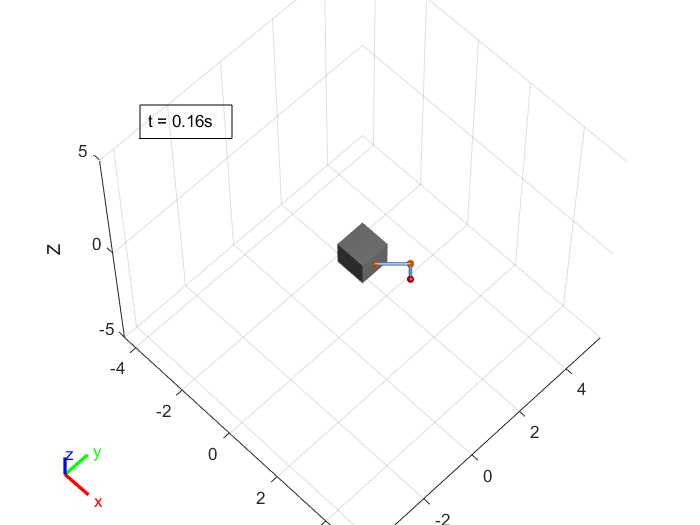

close all
filename = 'gifTest.gif';

% Parameters
dim = [.2 .5 .3 .3];
framesPerSecond = length(simRes.tout)/simRes.tout(end);
str = sprintf('t = %.2fs', 0);
sc.q = simRes.q.Data(:, :, 1);

% First frame
h_annot = annotation('textbox', dim,'String', str,'FitBoxToText','on');
sc.show('preserve', false, 'fast', true, 'visuals', 'on');
drawnow
% warning('off','all')

f = getframe;
[im,map] = rgb2ind(f.cdata,256,'nodither');
im(1,1,1,20) = 0;


for i = 1:length(simRes.q.Time)
    sc.q = simRes.q.Data(:, :, i);
    sc.show('preserve', false, 'fast', true, 'visuals', 'on');
    curT = i/framesPerSecond;
    str = sprintf('t = %.2fs', curT);    
    h_annot.set('String',str);
    drawnow

    f = getframe;
    im(:,:,1,i) = rgb2ind(f.cdata,map,'nodither');
%     
%     if i==1
%         exportgraphics(gcf, filename,'Append',false);
%     else
%         exportgraphics(gcf, filename,'Append',true);
%     end
end


% warning('on','all')

imwrite(im,map,filename,'DelayTime',1/framesPerSecond,'LoopCount',inf)